## MA438 - Lab 7: Greedy Algorithms (v2: updated after class 21 March)

Minor changes were made to the version available before class:

- This one outputs the sum of the weights of each spanning tree computed, to verify they are all the same.

- In Kurstal's algorithm, adds an edge providing the number of connected components is reduced.

clear;

## 1. Introduction

First we'll make a random graph that satisfies certain properties

- It has a specified number of vertices and a minimum number of edges

- It is connected (using a function defined at the end of the file).

- It has at least one cycle. Thus is it not a tree (which would make the whole thing rather too simple).

Is in Lab 5, we use the `rng()` function to ensure repeatability. You should remove that line later. Also: I'm not allowing the weight to be 7 because it is too hard to distinguish from 1!

rng(123);
N = 8;
MaxWeight = 10;
MinEdges = N*2;
G = graph();
G = G.addnode(N);
while ( (~IsConnected(G)) ...
      || (G.hascycles == false) || ...
      (G.numedges < MinEdges))
   s = randi(N);
   t = randi(N);
   w = randi(MaxWeight);
   if ( (s ~= t) && (G.findedge(s,t)==0) && (w ~= 7))
      G=G.addedge(s,t,w);
   end
end
fprintf('G has %d edges. Total weight of all these edges is %d\n', ...
   G.numedges, sum(G.Edges.Weight));
figure; plot(G,'EdgeLabel',G.Edges.Weight ); title('A graph, G')

### Using a MATLAB algorithm

We want to see how to compute minimum spanning trees. MATLAB hasa function to do this, which we'll use to verify our results.

T = minspantree(G);
figure; plot(T,'EdgeLabel',T.Edges.Weight); 
title('The min spanning tree of G')
h = plot(G,'Layout','force','EdgeLabel',G.Edges.Weight);
highlight(h,T);
title('G and a minimum spanning tree')
fprintf('T has %d edges. Total weight of the edges in T is %d\n', ...
   T.numedges, sum(T.Edges.Weight));

## 2. Krustal's algorithm

fprintf("%s\n%s\n", "2. Kurstal's Algorithm", ...
   "----------------------");

For a weighted graph, Kurstal's algorithm starts with $S$ as the subgraph of $G$ that has no edges (but it does have all the same vertices). That is, $G$ has $v$ components, where $v$ is the number of vertices.

It goes through all the edges in $G$ in order of their weight (least first). That edge is added to $S$ so long as it does not create a cycle. More correctly, it adds the first edge that would reduce the number of connected components. You can read more at [https://en.wikipedia.org/wiki/Kruskal%27s_algorithm](https://en.wikipedia.org/wiki/Kruskal%27s_algorithm)

To do this, we use that sort() returns the "key" for sorting a vector as its second return value.

edge_weights = G.Edges.Weight;
[~, ordering] = sort(edge_weights); % ordering is the key
S1 = graph();
S1 = S1.addnode(G.numnodes)

We also use that, in spite of its name, G.addedge(), does not add an edge to $G$, but returns a new graph that is the same as $G$, but with the edge added. 

k=0;
figure;
for e=ordering'
   v = G.Edges.EndNodes(e,:);
   w = G.Edges.Weight(e);
   newS1 =  S1.addedge(v(1), v(2),w);
   if (NumComponents(S1) == NumComponents(newS1)+1)
      k=k+1;
      S1=S1.addedge(v(1),v(2), w);
   figure
   g = plot(G,'Layout','force','EdgeLabel',G.Edges.Weight);
   highlight(g,S1)
   title_str = sprintf("Kusrstal Step %d", k);
   title(title_str)
   end
end

This implemenation is somewhat sub-optimal: we check if every edge can be added, even though, once $S$ has $N-1$ edges, we cannot add any more. An alternative way of determining if we can stop is if the graph is now connected. 

fprintf('S1 has %d edges. Total weight of the edges in S1 is %d\n', ...
   S1.numedges, sum(S1.Edges.Weight));

## 3. Prim's Algorithm

This algorithm differs from Kurstal's by starting with a graph, $S$, that has a single vertex. It chooses the edge from $G$ that is incident to it, and adds it (and a new vertex) to $S$. The edge chosens is the one of least weight. 

Next it picks the edge of least weight that is incident to one of those two, but not both, and adds it to $S$, and so on. In this way, it builds up a tree that eventually spans $G$.

The implemenation here is overly complicated, I think. Feel free to skip or, better still, come up with a better version.

edge_weights = G.Edges.Weight;
[~, ordering] = sort(edge_weights);
S2 = graph();
S2=S2.addnode(1);
k=0; 
e=ordering(1); % pick edge with lowest weight.
v = G.Edges.EndNodes(e,:);
w = G.Edges.Weight(e);
Added = [v(1), v(2)];
S2=S2.addedge(v(1), v(2), w);

while (S2.numedges < (G.numnodes-1))
   i = 2;
   EdgeAdded=false;
   while (~EdgeAdded)
      e=ordering(i); % pick edge with lowest weight.
      v = G.Edges.EndNodes(e,:);
      w = G.Edges.Weight(e);
      if ( sum(ismember(Added, v))==1)
         tmp = S2.addedge(v(1), v(2), w);
         if (~hascycles(tmp) )
            S2 = tmp;
            Added = unique([Added, v]);
            EdgeAdded = true;
            %fprintf("k=%d: Added (%d,%d). numedges = %d\n", ...
            %   k, v(1), v(2), S2.numedges);
            k=k+1;
         end
      end
      i=i+1;
   end
end
g = plot(G,'Layout','force','EdgeLabel',G.Edges.Weight);
highlight(g,S2)
plot(S2,'EdgeLabel',S2.Edges.Weight)
fprintf('S1 has %d edges. Total weight of the edges in S1 is %d\n', ...
   S1.numedges, sum(S1.Edges.Weight));

### Comparing three approaches

figure;
subplot(1,3,1); plot(T); title('MATLAB')
subplot(1,3,2); plot(S1); title('Kurstal')
subplot(1,3,3); plot(S2); title('Prim')

## 4. A Matrix-based version of Prim's

This version will be discussed in class.

A = full(G.adjacency('weighted'));
A(A==0)=inf; % mask indexing!
B = zeros(N);
U = 1;
V = setdiff(1:N, U);
k = 0;
while(k < (N-1))
   min_e = inf;
   for i = U
      for j = V % should be able to remove this for-loop.
         if (A(i,j) < min_e ) 
            min_e = A(i,j);
            I = i; J = j;
         end
      end
   end
   B(I,J)=A(I,J);
   U = union(U,J);
   V = setdiff(V,J);
   k=k+1;
end
B=B+B';
S3 = graph(B);
figure;
subplot(1,2,1); plot(S3,'EdgeLabel',S3.Edges.Weight)
subplot(1,2,2);
g = plot(G,'Layout','force','EdgeLabel',G.Edges.Weight);
highlight(g,S3)

## Exercises 3.11 from Problem Set 3

This is an exercise from Problem Set 3. 

(Provide your solution to this problem as a MATLAB Live script). Consider the graph below (previously seen in Exercise 3.9 from Lab 6).

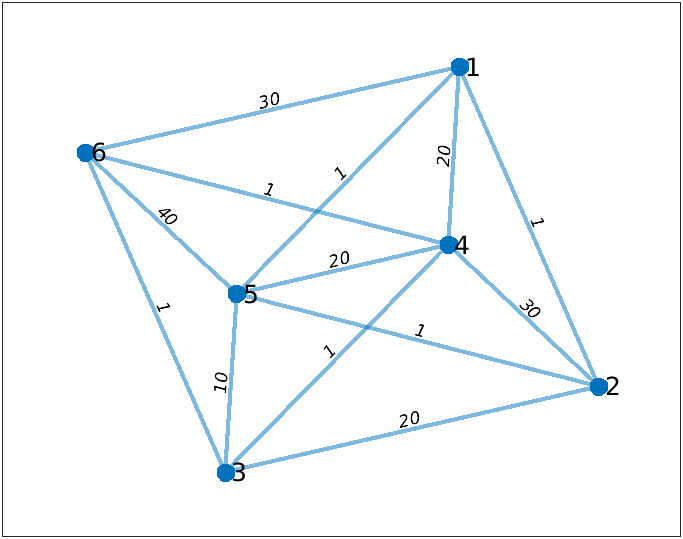

- Write a MATLAB script that that defines and plots this graph with that adjacency matrix. 

- Find and plot  a minimum spanning for the graph. 

- How many different matchings are possible of this graph? (You don't have to list them all).  

- Plot the graph, highlighting the matching with the maximum weight. 

## Useful functions

`IsConnected(G)` returns `true `if the graph $G$ is connected, and `false` otherwise.

function a = IsConnected(G)
  a = (max(G.distances, [], 'all')~=inf);
end

NumComponents(G) returns the number of components in the graph, $G$.

function num_con = NumComponents(G)
num_con = max(G.conncomp());
end